## Midterm - Engs 105: Comp Methods for PDEs I

Author: Aaryan Agrawal

Date: 2/7/2024

Instructor: Prof. Paulsen

clear; close all

### Parameters

D = 0.5;
L = 10;
h = 0.1;
k = 0.005;

tfinal = 100;

sigma = 0.1;
x0 = 5;

### Solution Mesh

x = [0:h:L];
t = [0:k:tfinal*k];

### Plot initial Conditions

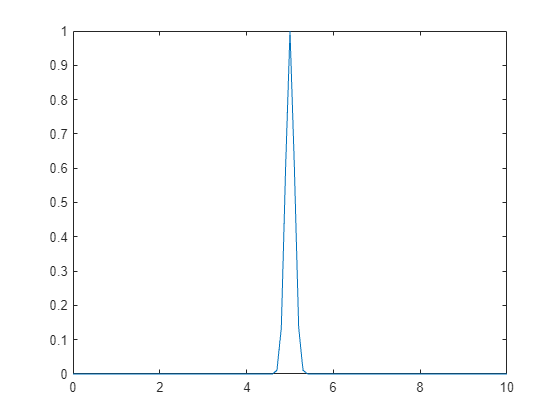

initial_cond = @(x) exp(-(x-x0).^2/(2*sigma*sigma));
plot(x, initial_cond(x))
ylabel("")

## Finite Difference Numerical Solution

### FD Equation A

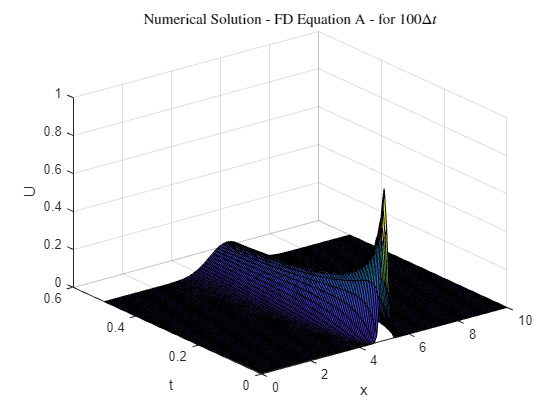

solutionA = readmatrix('solutionA.txt');
figure;
surf(x,t,solutionA);
ylabel('t')
xlabel('x')
zlabel('U')
title('Numerical Solution - FD Equation A - for $100 \Delta t$', 'Interpreter', 'latex');

### FD Equation B

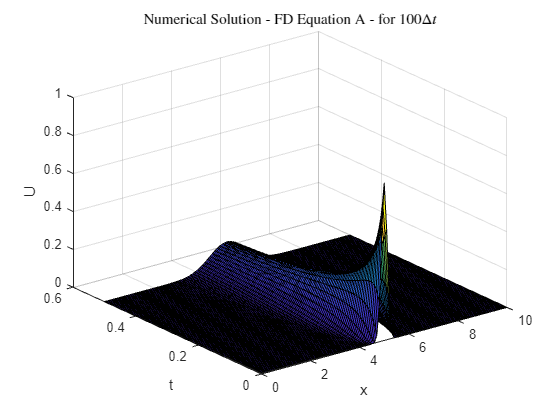

solutionB = readmatrix('solutionB.txt');
figure;
surf(x,t,solutionB);
ylabel('t')
xlabel('x')
zlabel('U')
title('Numerical Solution - FD Equation A - for $100 \Delta t$', 'Interpreter', 'latex');

## Stability & Accuracy

### A

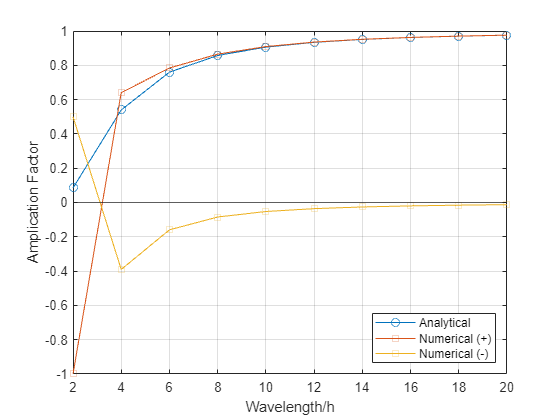


rAcc = 0.25;

%Analytical Amplification Factor
analyticGamma = @(r, sigmah) exp(-r.*sigmah.*sigmah);
lambdaOverh = [2:2:20];
sigmah = 2*pi./lambdaOverh;

%Numerical Analytical Factor for A
phi_func = @(sigmah) (2*cos(sigmah) - 2);
pA_func = @(sigmah) [1 -1-(3*rAcc/2)*(phi_func(sigmah)) (rAcc*phi_func(sigmah)/2)];
numericalGammaA = zeros([2, size(sigmah, 2)]);
for i = [1:size(sigmah, 2)]
    pA = pA_func(sigmah(i));
    numericalGammaA(:, i) = roots(pA);
end

figure
plot(lambdaOverh, analyticGamma(rAcc, sigmah), 'o-')
hold on
plot(lambdaOverh, numericalGammaA, 'square-')
yline(0)
yline(1)
yline(-1)
legend('Analytical', 'Numerical (+)', 'Numerical (-)', 'Location', 'southeast')
grid on
xlabel('Wavelength/h')
ylabel('Amplication Factor')

### B

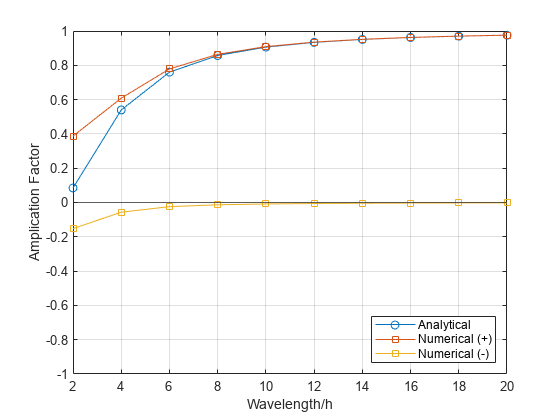

%Numerical Analytical Factor for B
pB_func = @(sigmah) [ 1-(5*rAcc/12)*(phi_func(sigmah)) -1-(8*rAcc/12)*(phi_func(sigmah)) phi_func(sigmah)*rAcc/12];
numericalGammaB = zeros([2, size(sigmah, 2)]);
for i = [1:size(sigmah, 2)]
    pB = pB_func(sigmah(i));
    numericalGammaB(:, i) = roots(pB);
end

figure
plot(lambdaOverh, analyticGamma(rAcc, sigmah), 'o-')
hold on
plot(lambdaOverh, numericalGammaB, 'square-')
yline(0)
yline(1)
yline(-1)
legend('Analytical', 'Numerical (+)', 'Numerical (-)', 'Location', 'southeast')
grid on
xlabel('Wavelength/h')
ylabel('Amplication Factor')

## Matlab Solution

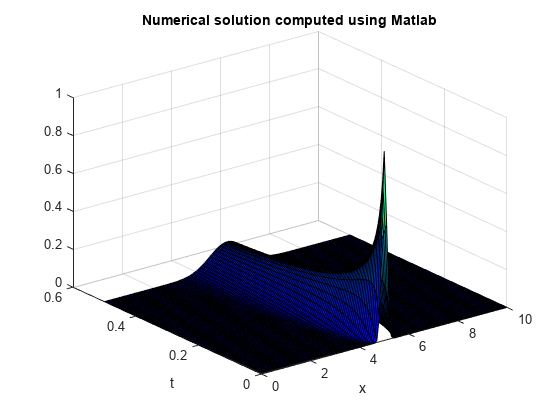

m = 0;
options = odeset('RelTol',1e-5,'AbsTol',1e-7);
mat_sol = pdepe(m,@pdex1pde,@pdex1ic,@pdex1bc,x,t,options);
mat_u = mat_sol(:,:,1);

figure;
surf(x,t,mat_u);
colormap(winter)
title('Numerical solution computed using Matlab')
xlabel('x')
ylabel('t')

### RMS Error w/ Numerical

diffA = rms(solutionA - mat_u, 'all')

diffA = 0.0034

diffB = rms(solutionB- mat_u, 'all')

diffB = 0.0032

### Comparing behaviour

% N = size(solutionA, 2);
% 
% xRange = [4.9:0.05:5];
% xRangeIndex = int32(xToIndex([4.9:h:5], h));
% figure;
% plot(x(xRangeIndex), initial_cond(x(xRangeIndex)))
% hold on
% xline(xRange)
% 
% 
% for xQuery = xRange
%     figure
%     subplot(1, 2, 1)
%     index = int32(xToIndex(xQuery, h));
%     Axx = solutionA(:, index);
%     Bxx = solutionB(:, index);
%     Mxx = mat_u(:, index);
%     plot(t, Mxx-Bxx)
% 
%     subplot(1, 2, 2)
%     plot(t, Axx)
% end


Evolution of L-2 Norm Error

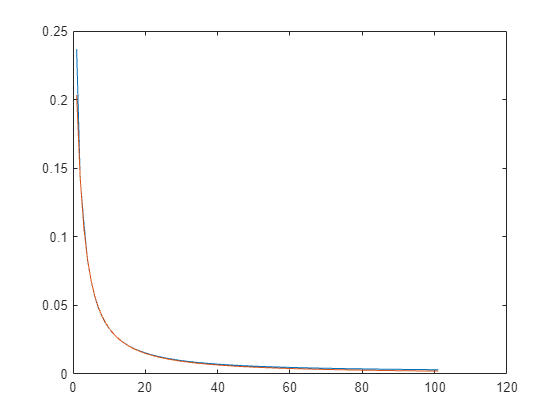

errorNormA = vecnorm(solutionA - mat_u, 2, 2);
errorNormB = vecnorm(solutionB - mat_u, 2, 2);
figure;
plot(errorNormA)
hold on
plot(errorNormB)

### Set up functions required to plot expected solution to problem using Matlab built-in PDE solvers

function [c, f, s] = pdex1pde(x,t,u,dudx)
D = 0.5;
c = 1;
f = D * dudx;
s = 0;
end

function u0 = pdex1ic(x)
sigma = 0.1;
x0 = 5;
u0 = exp(-(x - x0)^2/(2*sigma*sigma));
end

function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t)
pl = ul;
ql = 0;
pr = ur;
qr = 0;
end

### Other Utility Functions

function [index] = xToIndex(x,h)
    index = (x./h)+1;
end